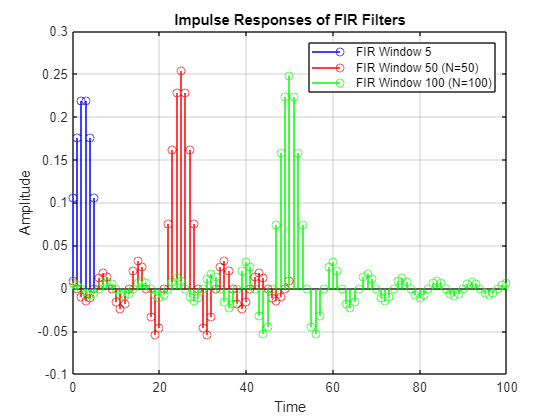

% Define the filter objects for all three cases
Hd1 = FIR_window_5;
Hd2 = FIR_window_50;
Hd3 = FIR_window_100;

% Obtain impulse responses
[h1, t1] = impz(Hd1);
[h2, t2] = impz(Hd2);
[h3, t3] = impz(Hd3);

% Plot all three impulse responses in the same figure
figure;
stem(t1, h1, 'b');
hold on;
stem(t2, h2, 'r');
hold on;
stem(t3, h3, 'g');
hold off;

xlabel('Time');
ylabel('Amplitude');
title('Impulse Responses of FIR Filters');
legend('FIR Window 5','FIR Window 50 (N=50)','FIR Window 100 (N=100)');
grid on;

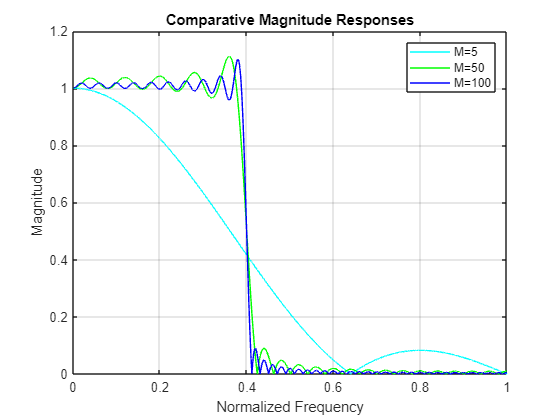

[H_5, w_5] = freqz(M_5_wc_4);
[H_50, w_50] = freqz(M_50_wc_4);
[H_100, w_100] = freqz(M_100_wc_4);


% Plot the magnitude responses
figure;
plot(w_5/pi, abs(H_5),'c');
hold on;
plot(w_50/pi, abs(H_50),'g');
hold on;
plot(w_100/pi, abs(H_100),'b');
hold off;
title('Comparative Magnitude Responses');
xlabel('Normalized Frequency');
ylabel('Magnitude');
legend('M=5', 'M=50', 'M=100');
grid on;

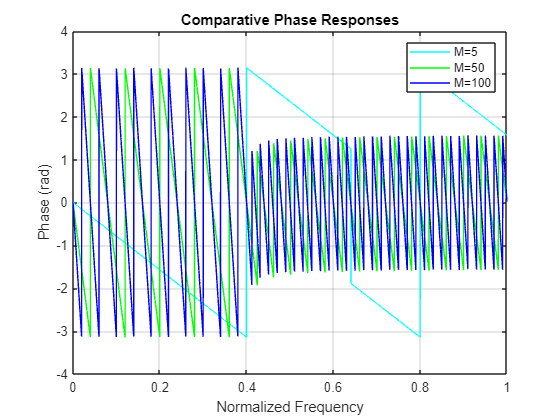

figure;
plot(w_5/pi, angle(H_5),'c');
hold on;
plot(w_50/pi, angle(H_50),'g');
hold on;
plot(w_100/pi, angle(H_100),'b');
hold off;
title('Comparative Phase Responses');
xlabel('Normalized Frequency');
ylabel('Phase (rad)');
legend('M=5', 'M=50', 'M=100');
grid on;

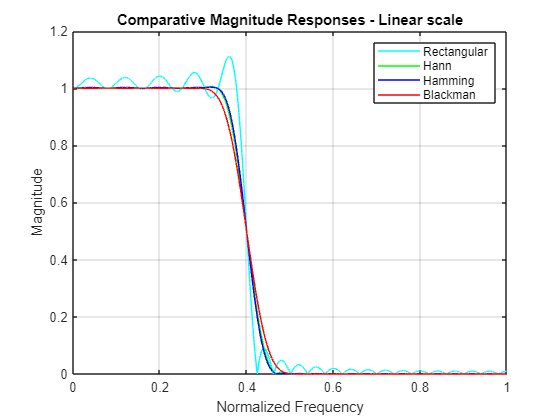

[rect_H_50, rect_W_50] = freqz(M_50_wc_4);
[hann_H_50, hann_W_50] = freqz(hann_M_50_wc_4);
[hamming_H_50, hamming_W_50] = freqz(hamming_M_50_wc_4);
[blackman_H_50, blackman_W_50] = freqz(blackman_M_50_wc_4);

% Plot the magnitude responses in linear scale
figure;
plot(rect_W_50/pi, abs(rect_H_50),'c');
hold on;
plot(hann_W_50/pi, abs(hann_H_50),'g');
hold on;
plot(hamming_W_50/pi, abs(hamming_H_50),'b');
hold on;
plot(blackman_W_50/pi, abs(blackman_H_50),'r');
hold off;
title('Comparative Magnitude Responses - Linear scale');
xlabel('Normalized Frequency');
ylabel('Magnitude');
legend('Rectangular','Hann','Hamming','Blackman');
grid on;

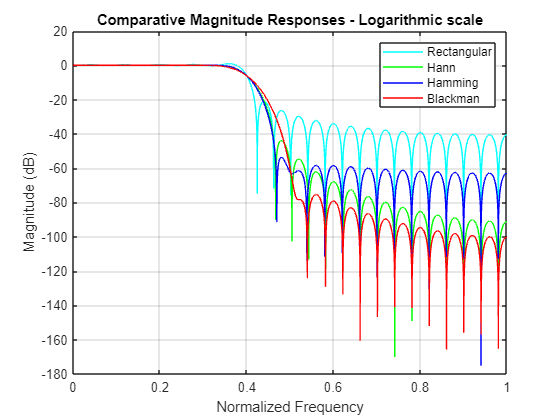

% Plot the magnitude responses in logarithmic scale
figure;
plot(rect_W_50/pi, 20*log10(abs(rect_H_50)),'c');
hold on;
plot(hann_W_50/pi, 20*log10(abs(hann_H_50)),'g');
hold on;
plot(hamming_W_50/pi, 20*log10(abs(hamming_H_50)),'b');
hold on;
plot(blackman_W_50/pi, 20*log10(abs(blackman_H_50)),'r');
hold off;
title('Comparative Magnitude Responses - Logarithmic scale');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('Rectangular','Hann','Hamming','Blackman');
grid on;

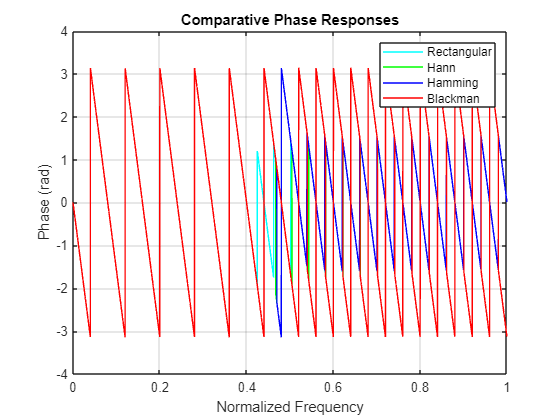

% Plot the phase responses 
figure;
plot(rect_W_50/pi, angle(rect_H_50),'c');
hold on;
plot(hann_W_50/pi, angle(hann_H_50),'g');
hold on;
plot(hamming_W_50/pi, angle(hamming_H_50),'b');
hold on;
plot(blackman_W_50/pi, angle(blackman_H_50),'r');
hold off;
title('Comparative Phase Responses');
xlabel('Normalized Frequency');
ylabel('Phase (rad)');
legend('Rectangular','Hann','Hamming','Blackman');
grid on;